# Moving mean filter designed to remove low frequency trends

## Read in Data 

%Specify location of file
outdir_2 = "C:\Users\uctsh\Documents\MATLAB\PipelineData";

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 1);
opts.VariableNames = ["Heave"];
opts.VariableTypes = ["double"];

%Read in table
wavefile = fullfile(outdir_2, "SHARC_SegmentIntegrate1.txt");
WaveTable = readtable(wavefile, opts);


## Remove mean

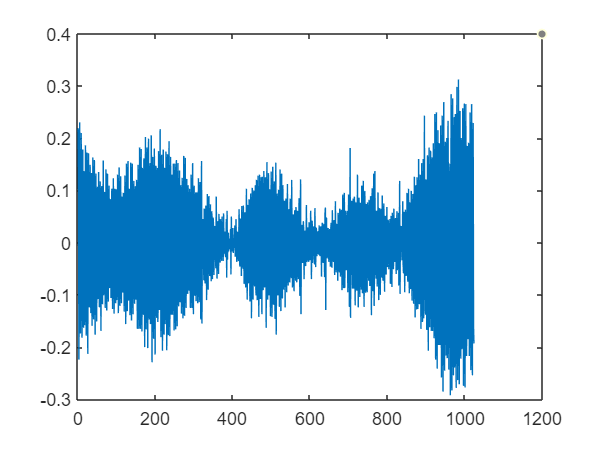

FFT_LENGTH  = 1024; 

meanData = mean(WaveTable.Heave);

heaveTemp = WaveTable.Heave;  

plot(heaveTemp);

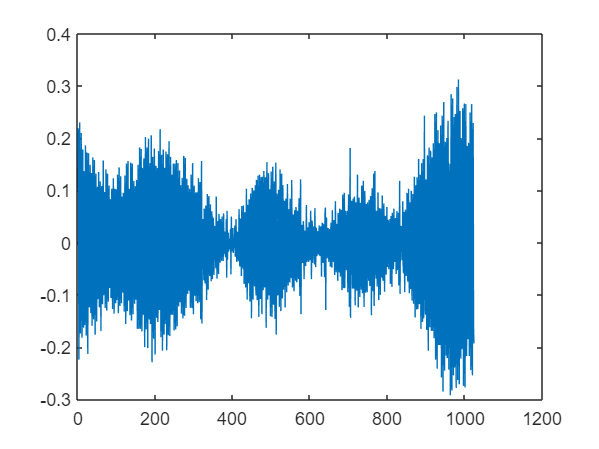


for i = 1:FFT_LENGTH 
    heaveTemp(i) = WaveTable.Heave(i) - meanData;
end

plot(heaveTemp);

## Detrending filter 

RC Highpass filter 


k = 0.95;
detrendOutput = WaveTable.Heave;
detrendTemp = zeros(FFT_LENGTH);
s = zeros(FFT_LENGTH); 

s(1) = 0;

for i= 2:FFT_LENGTH
     s(i)= detrendOutput(i) + k*(s(i-1));
     detrendTemp(i) = detrendOutput(i) - (1 - k)*(s(i));
end


## Plot Outputs 

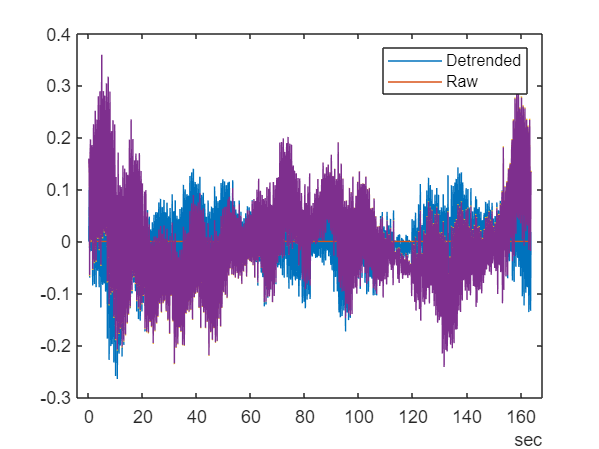

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);

plot(WaveTimeTable.Time, detrendTemp, WaveTimeTable.Time, detrendOutput, WaveTimeTable.Time, detrend(detrendOutput));
legend("Detrended", "Raw");

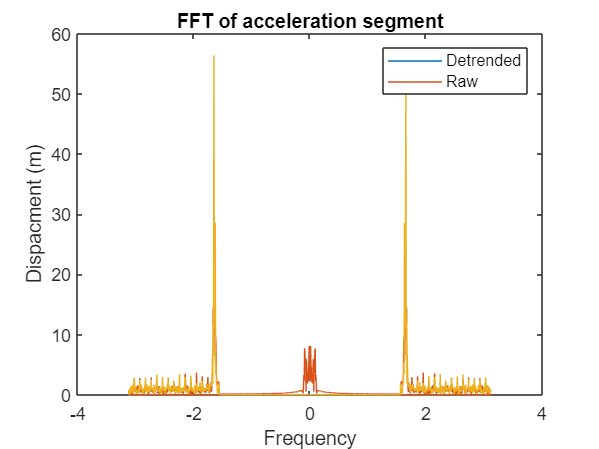



%Check frequency components of output
Fs = 6.25; %104/16; %6.25; 
Nfft = 1024; 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft;

WaveFFTDetrend = fft(detrendTemp);
WaveFFTRaw = fft(WaveTable.Heave);


plot(f, fftshift(abs(WaveFFTDetrend)), f, fftshift(abs(WaveFFTRaw)));
legend("Detrended", "Raw");
xlabel("Frequency");
ylabel("Dispacment (m)");
title("FFT of acceleration segment");